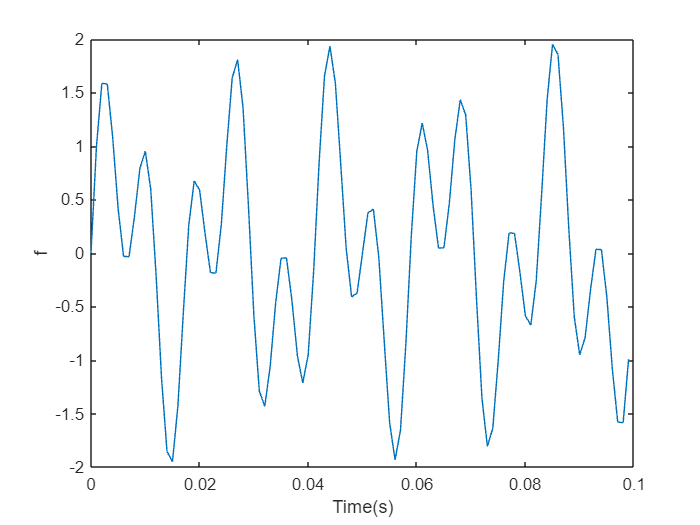

% Code is partly courtesy of Brunton and Kutz (2023) text 

dt = .001;
t = 0:dt:8;
f = sin(2*pi*50*t) + sin(2*pi*120*t); % Sum of 2 frequencies

% play audio at sampling rate FS and plot signal (just first 100 time steps)
FS = 4410/4; sound(f,FS);
figure;plot (t(1:100),f(1:100))
xlabel('Time(s)'); ylabel('f')

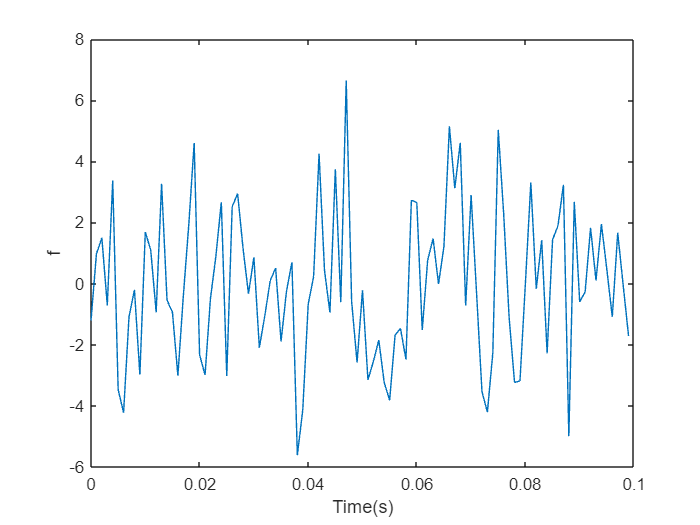

f_noisy = f + 2.5*randn(size(t)); % Add some noise

% play audio at sampling rate FS and plot signal (just first 100 time steps)
FS = 4410/4; sound(f_noisy,FS);
figure;plot (t(1:100),f_noisy(1:100))
xlabel('Time(s)'); ylabel('f')

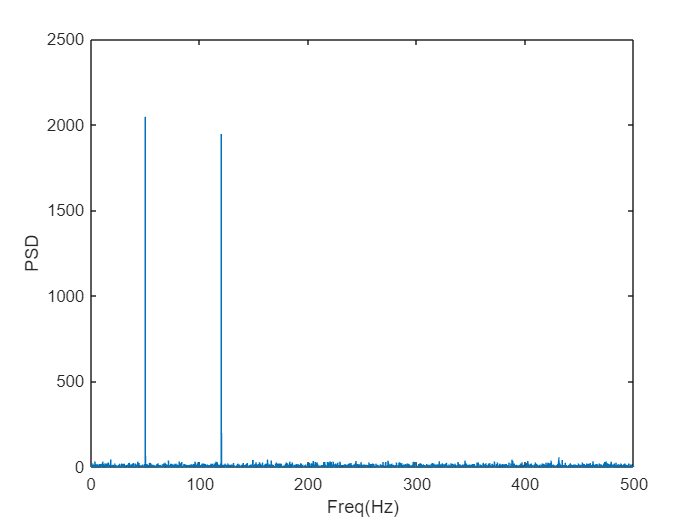

%% Compute the Fast Fourier Transform FFT
n = length(t);
fhat = fft(f,n); % Compute the fast Fourier transform
PSD = fhat.*conj(fhat)/n; % Power spectral density (power per freq)
freq = 1/(dt*n)*(0:n); % Create x-axis of frequencies in Hz

fhat_noisy = fft(f_noisy,n); % Compute the fast Fourier transform
PSD_noisy = fhat_noisy.*conj(fhat_noisy)/n; % Power spectral density (power per freq)
L = 1:floor(n/2); % Only plot the first half of freqs

figure;plot(freq(L),PSD_noisy(L))
xlabel('Freq(Hz)'); ylabel('PSD');hold on

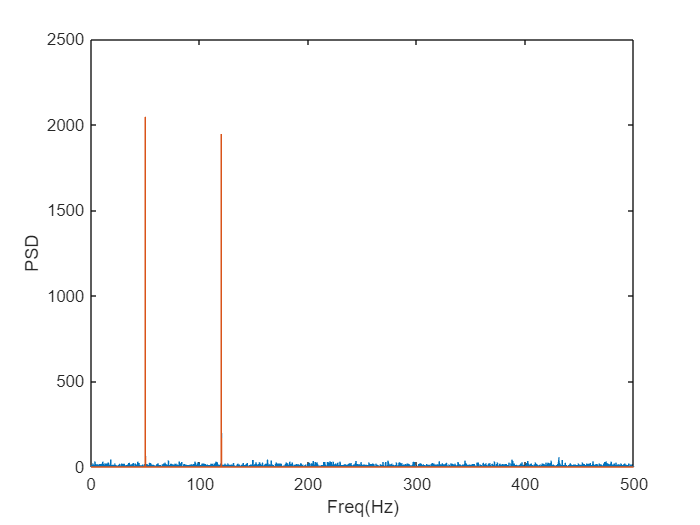


%% Use the PSD to filter out noise
indices = PSD_noisy>100; % Find all freqs with large power
PSDclean = PSD_noisy.*indices; % Zero out all others
fhat_noisy = indices.*fhat_noisy; % Zero out small Fourier coeffs. in Y
ffilt = ifft(fhat_noisy); % Inverse FFT for filtered time signal

% plot(L,PSDclean(1:floor(n/2)))
plot(freq(L),PSDclean(L))

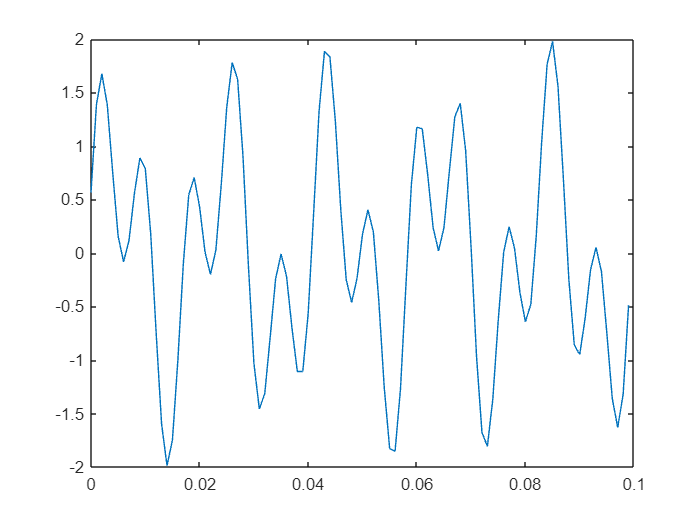

figure;plot (t(1:100),ffilt(1:100))